# Optical Communications Channel with OOK and DD

The following code simulates the transmitter, channel and reciever of an optical communications system which uses on-off keying and direct detection. The effects of AWGN and CD are investigated.

## Optical Transmitter

The transmitter consists of the following elements:

- Current modulator - which turns the current to a laser on or off depending on the bit sequence to be transferred.

- AWGN generator - which adds zero-mean AWGN to the current driving the laser

- Laser - which turns on and off depending on the current. The laser linewidth can be varied to analyse the effect of CD.

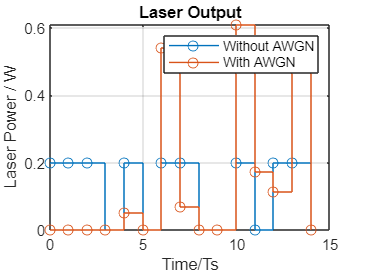

clear all; clearvars;

% Random sequence of source bits is created
NSequences = 25; % No. of random sequences generated
SpS = 1; % Samples per symbol
Rs = 1e10; % Symbol rate in symbols/s
NBits = 500000; % No. of bits
NSymb = NBits/SpS; % No. of symbols
sourceBits = randi([0 1], NBits, NSequences); % Vector of source bits

% Laser parameters
laserPw = 0.2; % Laser output power in W
laserLW = 2; % Laser linewidth in kHz

% The laser current is turned on and off according to the bit sequence
laserOut = sourceBits*laserPw;
laserOut_AWGN = zeros(size(laserOut));

% Adding AWGN to laser output
SNRb_dB = [0:1:NSequences-1]'; % SNR per bit in dB
SNRb_Lin = zeros(size(SNRb_dB));
AWGN_StdDev = zeros(size(SNRb_dB));

for i=1:size(SNRb_dB,1)
    SNRb_Lin(i,1) = 10^(SNRb_dB(i,1)/10); % linear SNR per bit
    AWGN_StdDev(i,1) = sqrt(laserPw/(2*SNRb_Lin(i,1))); % AWGN Standard deviation
    laserOut_AWGN(:,i) = laserOut(:,i) + AWGN_StdDev(i,1)*randn(size(laserOut, 1),1); % Noisy laser output
end

laserOut_AWGN(laserOut_AWGN < 0) = 0;

t = [0: 1 : NSymb - 1];
stairs(t(1:15), laserOut(1:15), 'o-');
title('Laser Output');
xlabel('Time/Ts');
ylabel('Laser Power / W');
grid on

hold on
stairs(t(1:15), laserOut_AWGN(1:15), 'o-');
legend("Without AWGN", "With AWGN")
hold off

## Optical Channel

The optical channel is modelled to add CD

% Optical channel parameters
Z_f = 100; % Impedance of fibre material in Ohms
n = 1.4; % Refractive index of fibre material

channelOut = laserOut_AWGN;

% % Adding CD
% laserOut_CD = ones(NBits,1)*sqrt(laserPw); % Initialising laser output + CD
% if laserLW ~= 0 
%     Ts = 1/(SpS*Rs); % Period between samples
% 
%     % Calculating the phase noise:
%     Var = 2*pi*(laserLW*10^3)*Ts;
%     Delta_theta = sqrt(Var)*randn(size(NBits,1),1);
%     Theta = cumsum(Delta_theta);
% 
%     E = E.*repmat(exp(1i*Theta),1,size(E,2)); % Adding phase noise to the optical signal:
% end

## Optical Reciever

The receiver consists of the following elements:

- Photodetector - which outputs a current depending on the magnitude of the electric field it is exposed to

- Transimpedance amplfier (TIA) - which converts the current output from the photodetector to an amplified voltage

- ADC - which samples the output voltage from the TIA

- Decoder - which maps the samples from the ADC to symbols (0 or 1)

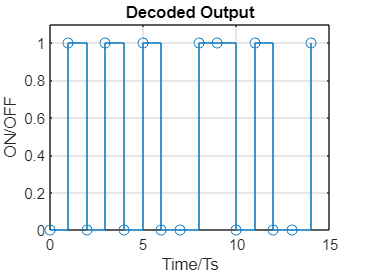

% Receiver parameters
eta_ph = 0.3; % Responsivity of photodetector
TIA_gain = 1; % Gain of TIA

% Photodetection process
E = sqrt(2*Z_f*channelOut); % Electric field strength at the output of the fibre
E_high = sqrt(2*Z_f*laserPw); % Electric field strength corresponding to 1
I_ph = eta_ph*E.^2; % Current output from photodetection

Vout = I_ph*TIA_gain; % Output from the TIA amplifier
V_high = TIA_gain*eta_ph*E_high^2; % Voltage corresponding to 1

ADC_out = zeros(size(Vout));

for i=1:size(Vout,2)
    ADC_out(:,i) = Vout(1:SpS:size(Vout,1), i); % ADC Output
end

ADC_out(ADC_out < V_high/2) = 0; % Setting all voltage levels less than V_high/2 to 'low'
ADC_out(ADC_out >= V_high/2) = 1; % Setting all voltage levels greater or equal to V_high/2 to 'low'

stairs(t(1:15), ADC_out(1:15), "o-");
title('Decoded Output');
xlabel('Time/Ts');
ylabel('ON/OFF');
ylim([0, 1.1])
grid on

## BER vs SNR

The following code calculates the BER as a function of the SNR per bit of the AWGN

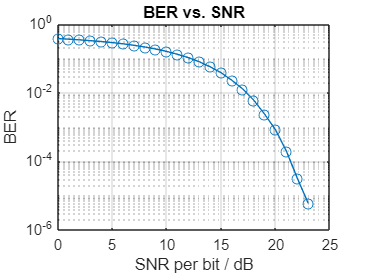

BER = zeros(size(SNRb_dB));

for i=1:size(BER,1)
    [~, BER(i,1)] = biterr(sourceBits(:,i), ADC_out(:,i));
end

semilogy(SNRb_dB, BER, 'o-')
title("BER vs. SNR")
ylabel("BER")
xlabel("SNR per bit / dB")
grid on